# Part I: Spike Train Statistics

load('spiketrain1.mat')

## A) Spiketrain Bin Rep.

timestep = timeaxis(2) - timeaxis(1);
samplingFreq = 1/timestep; %Sampling frequency

thresh = -30; %Appropriate thereshold

%Find all indices and create spiketimes array
i = 1;
l = length(Vm);
for j=2:2:l
    if (Vm(j)>-30 && Vm(j-1)<=-30)
        sp(i) = j*timestep;
        i = i+1;
    end
end

%Compute spiketrain binary vectors
bin_1 = spikeTrainBin(sp, timeaxis, 0.001);
bin_05 = spikeTrainBin(sp, timeaxis, 0.0005);
bin_01 = spikeTrainBin(sp, timeaxis, 0.0001);

**1)** Vm was sampled at a a frequency of 10.417 kHz

**2) **I chose -30mV as an appropriate threshold.

## B) Interspike Interval Statistics

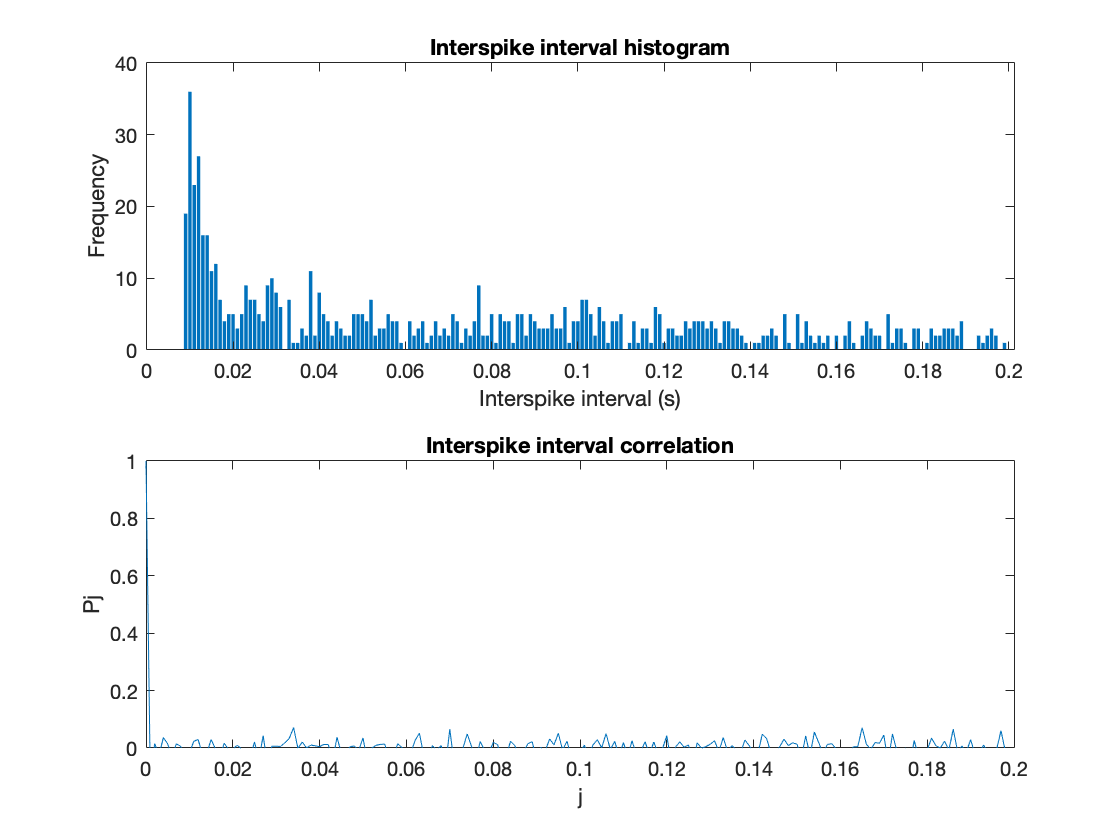

% ISI calculation
Isi = diff(sp);
binW = 0.001:0.001:0.2;

spikeHist = histcounts(Isi, binW); 
spikeHist(end+1) = 0;
figure(1); subplot(2, 1, 1);
bar(binW, spikeHist);
xlabel('Interspike interval (s)');
ylabel('Frequency');
title('Interspike interval histogram');

% Interspike Interval Correlation Coefficients
CV = std(Isi)/mean(Isi);
[c, lags] = xcorr(Isi - mean(Isi), 'coeff', 200);
figure(1); subplot(2, 1, 2);
plot(lags*0.001, c);
ylim([0 inf]);
xlim([0 inf]);
xlabel('j');
ylabel('Pj');
title('Interspike interval correlation');

**3) **The coefficiant of variation is CV = 1.0020. This neuron is approximately as variable as a Poisson process.

**4)  **As seen in the graph above, the ISI correlation is approximately 0 for all j != 0 which implies it is a renewal process.

## C) Autocorrelation function and Power spectrum

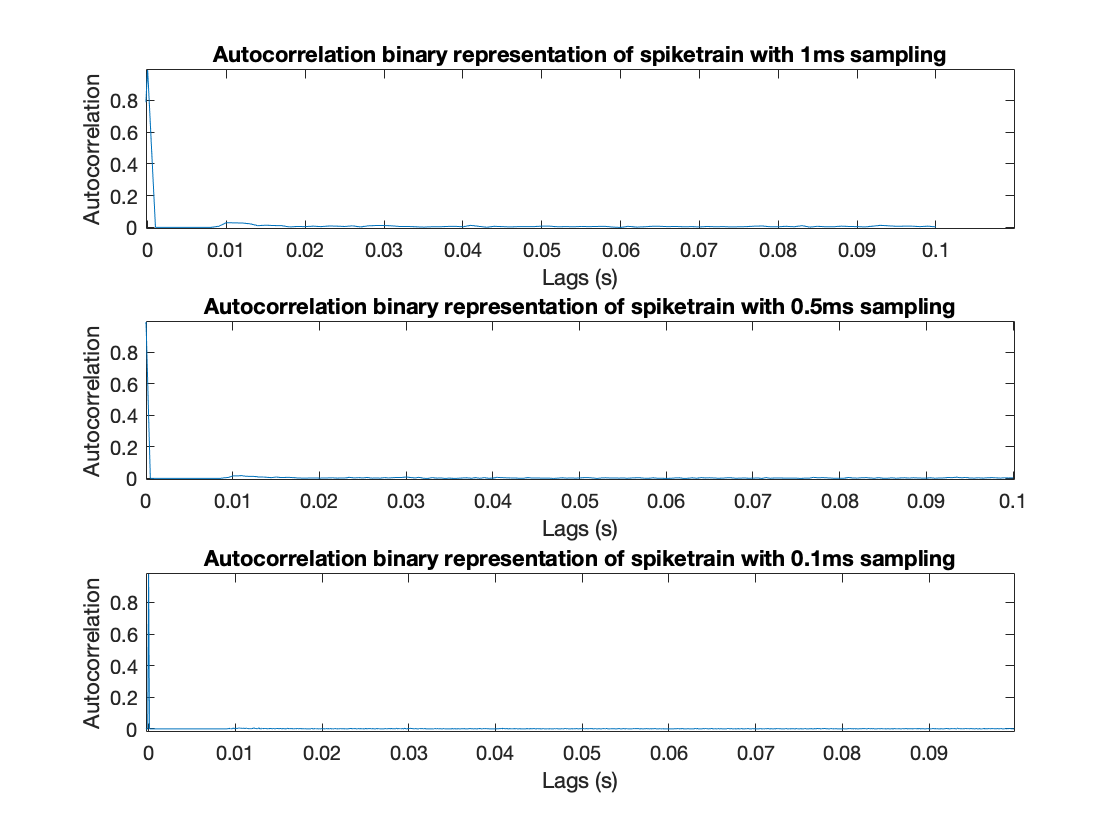

%Autocorrelation functions
[c_train1, lags_train1] = xcorr(bin_1, 0.1/0.001, 'coeff');
[c_train05, lags_train05] = xcorr(bin_05, 0.1/0.0005, 'coeff');
[c_train01, lags_train01] = xcorr(bin_01, 0.1/0.0001, 'coeff');
figure(2); subplot(3, 1, 1); 
plot(lags_train1*0.001, c_train1);
axis tight;
xlabel('Lags (s)');
ylabel('Autocorrelation');
title('Autocorrelation binary representation of spiketrain with 1ms sampling');
xlim([-0.0002 0.1099]);
ylim([-0.01 0.99]);

figure(2); subplot(3, 1, 2); 
plot(lags_train05*0.0005, c_train05);
axis tight;
xlabel('Lags (s)');
ylabel('Autocorrelation');
title('Autocorrelation binary representation of spiketrain with 0.5ms sampling');
xlim([-0.0000 0.1001]);
ylim([-0.01 0.99]);

figure(2); subplot(3, 1, 3); 
plot(lags_train01*0.0001, c_train01);
axis tight;
xlabel('Lags (s)');
ylabel('Autocorrelation');
title('Autocorrelation binary representation of spiketrain with 0.1ms sampling');
xlim([-0.0003 0.0998]);
ylim([-0.02 0.98]);

**1) **The neuron's absolute refractory period is  ~ 9 ms. As can be seen in the graphs there are periods of spiking followed by a flat line and so on suggesting that the neuron does spike in packets.

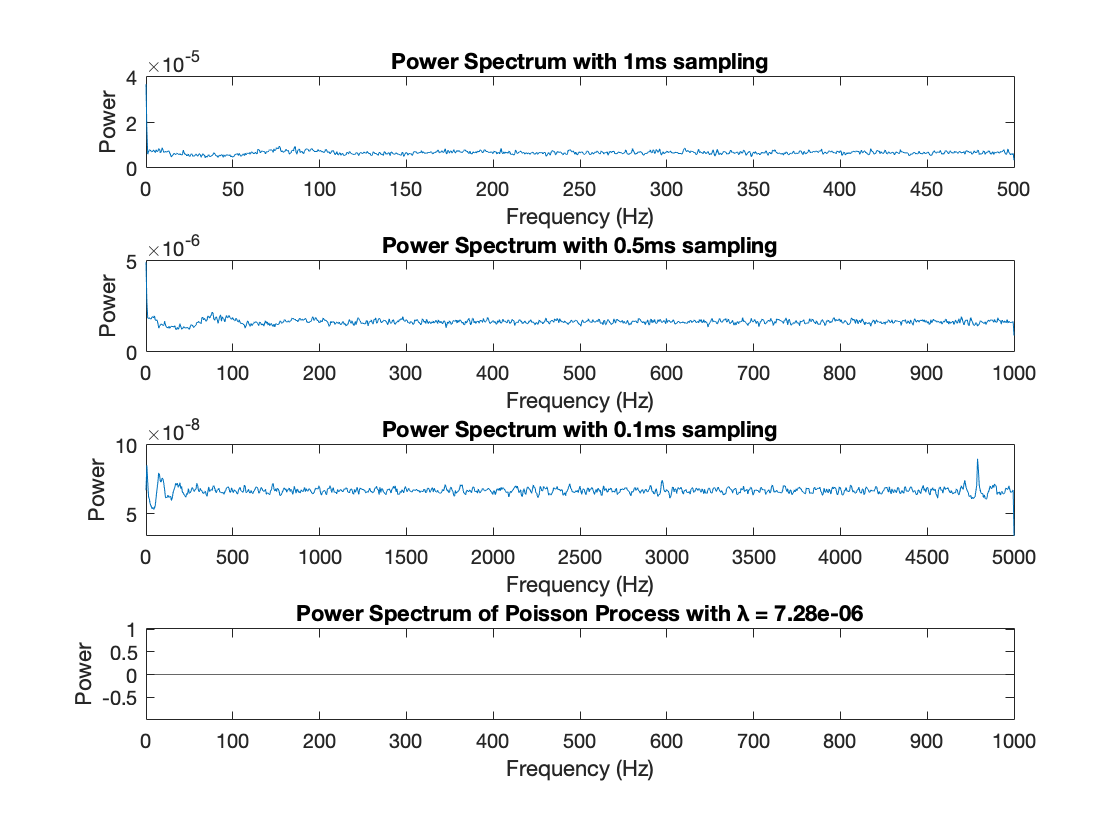

%Power spectra
[pxx_1,f_1]=pwelch(bin_1,bartlett(2048),1024,2048,1/0.001);
figure(3); subplot(4, 1, 1)
plot(f_1, pxx_1./2);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum with 1ms sampling');

[pxx_05,f_05]=pwelch(bin_05,bartlett(2048),1024,2048,1/0.0005);
figure(3); subplot(4, 1, 2)
plot(f_05, pxx_05./2);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum with 0.5ms sampling');

[pxx_01,f_01]=pwelch(bin_01,bartlett(2048),1024,2048,1/0.0001);
figure(3); subplot(4, 1, 3)
plot(f_01, pxx_01./2);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum with 0.1ms sampling');

figure(3); subplot(4, 1, 4)
yline(7.2750e-06);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Power Spectrum of Poisson Process with λ = 7.28e-06'); xlim([0 1000]);

**2) **As the sampling frequency increases, the density at which the spectrum "settles" over time decreases. The firing rate of this neuron is 7.2750e-06 Hz. 

## Part II Measures of Neural Encoding

clear; load('spiketrain2.mat');

## A) Raster plots and PSTH

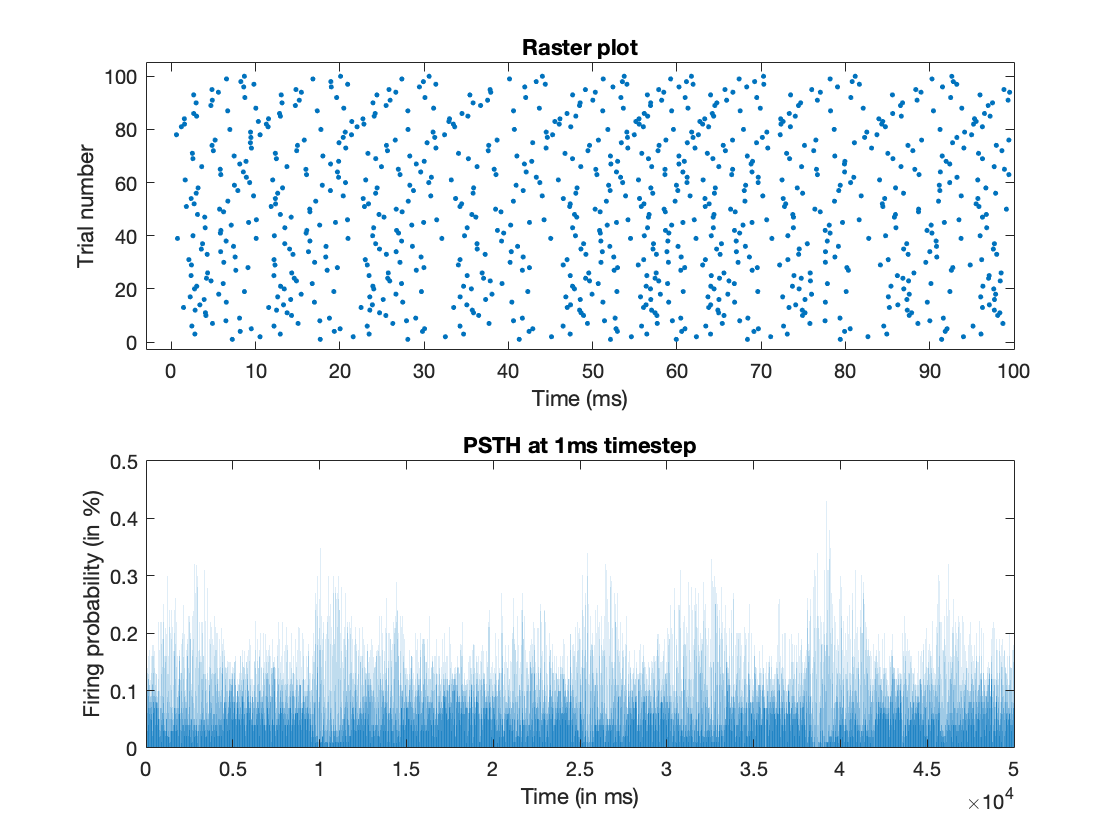

% Raster plot
subplot(2, 1, 1); plot(data(:,2), data(:,1), '.');
xlabel('Time (ms)');
ylabel('Trial number');
title('Raster plot');
xlim([-3 100]);
ylim([-3 105]);
% PSTH
binW = 1;
numTrials = length(unique(data(:,1))); % Number of trials
psth = histcounts(data(:,2),1:50000);
psth = psth /numTrials / binW;

subplot(2, 1, 2); bar(psth);
xlabel('Time (in ms)');
ylabel('Firing probability (in %)');
title('PSTH at 1ms timestep');
xlim([0 50000]);
ylim([0 0.5]);

1

## B) Cross correlation function and transfer function

% Cross-correlation
timeStep = 1/2000; 
numBins = 2000*50; 
bin = zeros(100,numBins);
tBin = round(data(:,2)/.5);
bin(tBin) = 1; 


[cor1,lag1] = xcorr(bin(1,:),stim,200,'unbiased');
subplot (2, 1, 1)
plot(lag1,cor1, '.b')
hold on

[cor20,lag20] = xcorr(bin(20,:),stim,200,'unbiased');
plot(lag20,cor20, '.g');
hold on;

[cor_all,lag_all] = xcorr(mean(bin,1),stim,200,'unbiased');
plot(lag_all,cor_all, '.r');

legend('Trial 1','Trial 20','Averaged Trials');
xlabel('Lag (ms)');
ylabel('Cross-correlation');
title('Cross-correlation between Stimulus and Trials');

**1) **The cross-correlation between trial 1, trial 20 and averaged trials is pretty much the same. This suggests that the stimulus response relation is consistent across trials.

% Cross spectrum
[pxy,f]=cpsd(bin(1,:),stim,bartlett(2048),1024,2048,2000);
subplot(2, 1, 2);
plot(f,pxy./2);

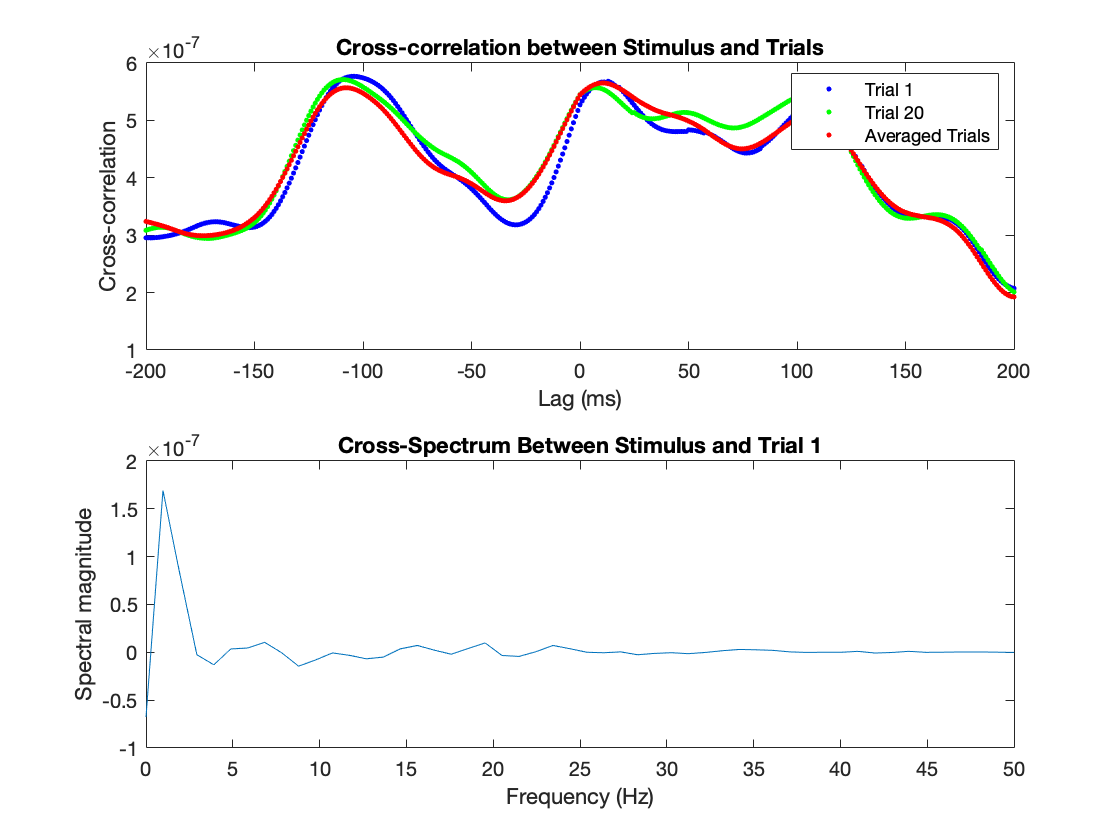

xlabel('Frequency (Hz)');
ylabel('Spectral magnitude');
title('Cross-Spectrum Between Stimulus and Trial 1');
xlim([0 50]);

## C) Signal-to-noise Ratio

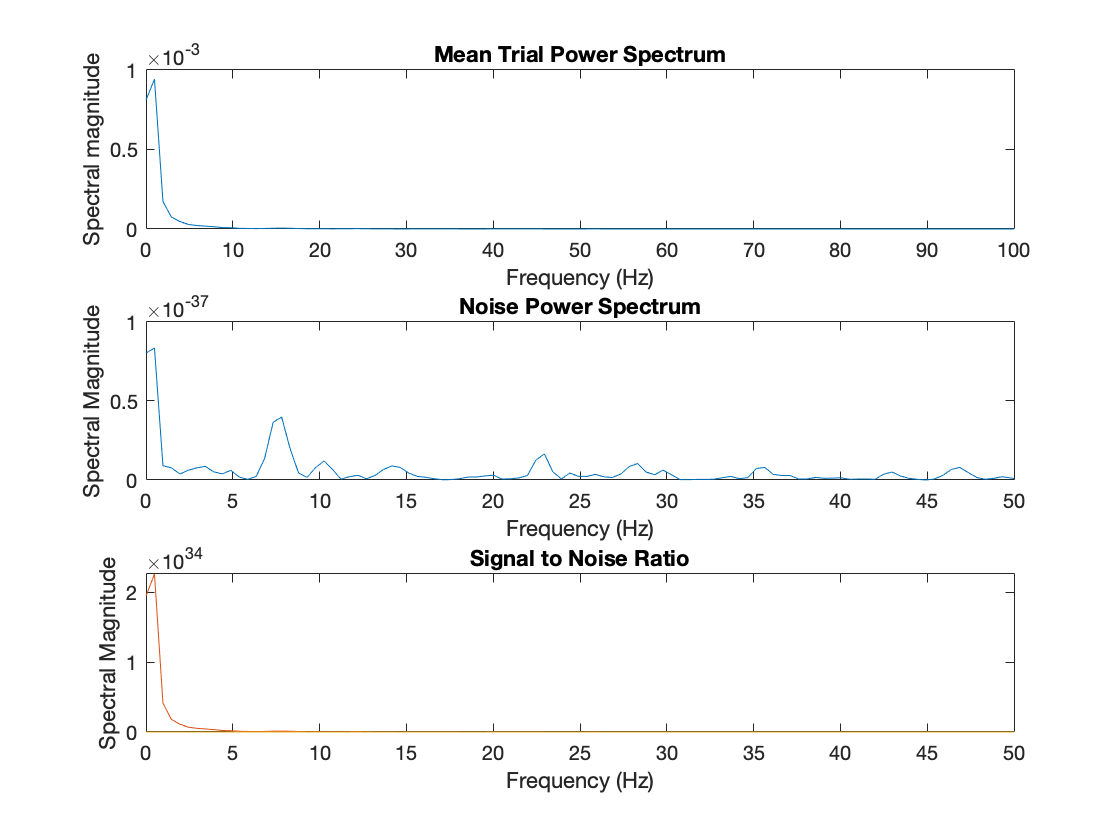

% Mean
[pxx, fp] = pwelch(mean(bin, 1), bartlett(2048), 1024, 2048, 2000);
figure(7); subplot(3, 1, 1); plot(fp, pxx./2);
xlabel('Frequency (Hz)');
ylabel('Spectral magnitude');
title('Mean Trial Power Spectrum');
xlim([0 100]); 

%Trials - Mean (Noise)
diffBin=bin;
for i=1:100
    diffBin(i,:) = bin(i,:) - mean(bin,1);
end
meanDiff=mean(diffBin,1);

[pxxDiff,fpDiff]=pwelch(meanDiff,bartlett(2048),1024,2048,2000);
pxxDiff=pxxDiff/2;
fpDiff=fpDiff/2;

figure(7); subplot(3, 1, 2); plot(fpDiff,pxxDiff); % Mean vs Noise
xlabel('Frequency (Hz)');
ylabel('Spectral Magnitude');
title('Noise Power Spectrum');
xlim([0 50]); 

%Signal-to-Noise Ratio
snr=pxx/pxxDiff;
figure(7); subplot(3, 1, 3); plot(fpDiff,snr);
xlabel('Frequency (Hz)');
ylabel('Spectral Magnitude');
title('Signal to Noise Ratio');
xlim([0 50]);